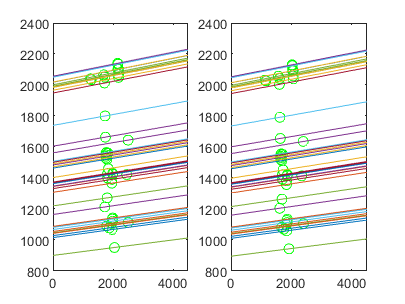

clear, clc, close all

% I1 = rgb2gray(imread('elephant_on_grid_new/DSC_0712.jpg'));
% I2 = rgb2gray(imread('elephant_on_grid_new/DSC_0713.jpg'));

% Elephant head
I1 = rgb2gray(imread('DSC_0714.JPG'));
I2 = rgb2gray(imread('DSC_0715.JPG'));

% Elephant body
% I1 = rgb2gray(imread('Task 5 pics/DSC_0729.JPG'));
% I2 = rgb2gray(imread('Task 5 pics/DSC_0730.JPG'));

% Elephant body new
% I1 = rgb2gray(imread('Task 5 pics/DSC_0729.JPG'));
% I2 = rgb2gray(imread('Task 5 pics/DSC_0730.JPG'));

% Epipolar lines
epipole_draw(I1, I2)

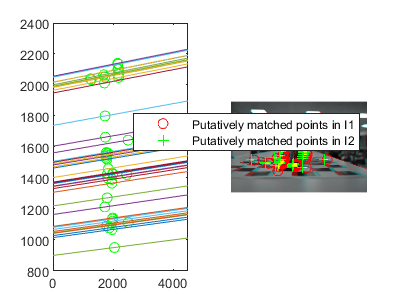

% Rectify images and draw epipoles:

blobs1 = detectSURFFeatures(I1);%, 'MetricThreshold', 2000);
blobs2 = detectSURFFeatures(I2);%, 'MetricThreshold', 2000);

[features1, validBlobs1] = extractFeatures(I1, blobs1);
[features2, validBlobs2] = extractFeatures(I2, blobs2);

indexPairs = matchFeatures(features1, features2);

matchedPoints1 = validBlobs1(indexPairs(:,1),:);
matchedPoints2 = validBlobs2(indexPairs(:,2),:);
matchedPoints1L = matchedPoints1.Location;
matchedPoints2L = matchedPoints2.Location;

showMatchedFeatures(I1, I2, matchedPoints1L, matchedPoints2L);
legend('Putatively matched points in I1', 'Putatively matched points in I2');

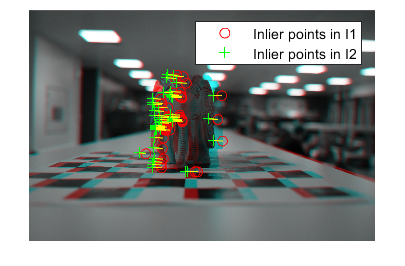


[fMatrix, epipolarInliers, status] = estimateFundamentalMatrix(...
  matchedPoints1L, matchedPoints2L, 'Method', 'RANSAC', ...
  'NumTrials', 10000, 'DistanceThreshold', 0.1, 'Confidence', 99.99);

if status ~= 0 || isEpipoleInImage(fMatrix, size(I1)) ...
  || isEpipoleInImage(fMatrix', size(I2))
  error(['Either not enough matching points were found or '...
         'the epipoles are inside the images. You may need to '...
         'inspect and improve the quality of detected features ',...
         'and/or improve the quality of your images.']);
end
inlierPoints1 = matchedPoints1(epipolarInliers, :);
inlierPoints2 = matchedPoints2(epipolarInliers, :);
inlierPoints1L = inlierPoints1.Location;
inlierPoints2L = inlierPoints2.Location;

figure;
showMatchedFeatures(I1, I2, inlierPoints1L, inlierPoints2L);
legend('Inlier points in I1', 'Inlier points in I2');

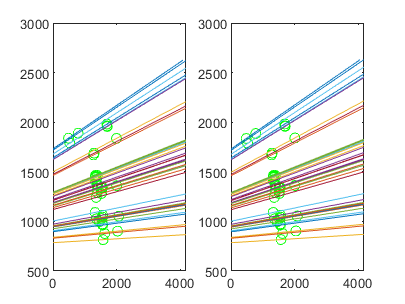



[t1, t2] = estimateUncalibratedRectification(fMatrix, ...
  inlierPoints1L, inlierPoints2L, size(I2));

tform1 = projective2d(t1);
tform2 = projective2d(t2);

[I1Rect, I2Rect] = rectifyStereoImages(I1, I2, tform1, tform2);
%[I1Rect, I2Rect] = rectifyStereoImages(I1, I2, t1, t2);

epipole_draw(I1Rect, I2Rect)

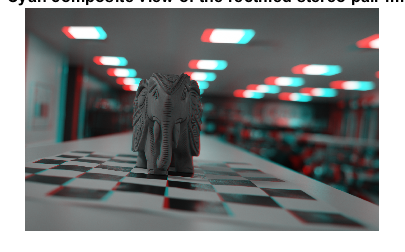


A = stereoAnaglyph(I1Rect,I2Rect);
figure
imshow(A)
title('Red-Cyan composite view of the rectified stereo pair image')

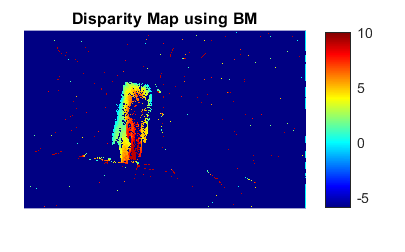

disparityRange = [-6 10];
disparityMapBM = disparityBM(I1Rect,I2Rect,'DisparityRange',...
    disparityRange,'UniquenessThreshold',20);

figure
imshow(disparityMapBM,disparityRange)
title('Disparity Map using BM')
colormap jet
colorbar

**DEPTH MAP FOR BM**

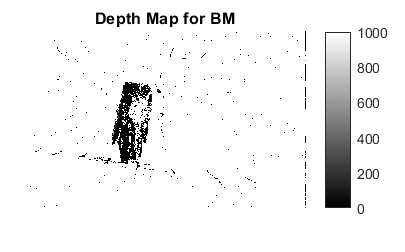

f = 18;
b = 2;
disparityMapBM2 = double(disparityMapBM);

depthBM = nan(size(disparityMapBM2));
maxDep = 1000;
for i = 1:size(depthBM, 1)
    for j = 1:size(depthBM, 2)
        if(~isnan(disparityMapBM2(i,j)))
            depthBM(i,j)= (f*b)/(disparityMapBM2(i,j));
        else
            depthBM(i,j)= maxDep;
        end
    end
end
figure
imshow(depthBM, [0 maxDep])
title('Depth Map for BM')
colormap;
colorbar

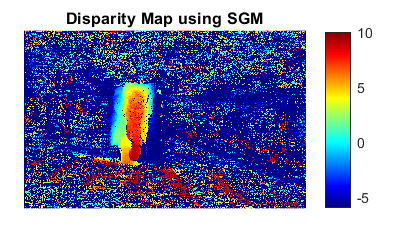

disparityRange = [-6 10];
disparityMapSGM = disparitySGM(I1Rect,I2Rect,'DisparityRange',disparityRange,'UniquenessThreshold',20);
figure
imshow(disparityMapSGM,disparityRange)
title('Disparity Map using SGM')
colormap jet
colorbar

**DEPTH MAP for SGM**

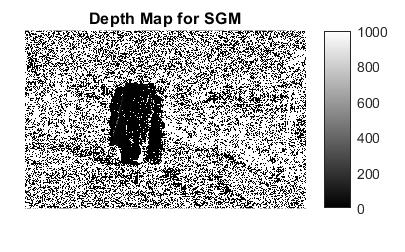

f = 18;
b = 2;
disparityMapSGM = double(disparityMapSGM);
depthSGM = nan(size(disparityMapSGM));
maxDep = 1000;
for i = 1:size(depthSGM, 1)
    for j = 1:size(depthSGM, 2)
        if(~isnan(disparityMapSGM(i,j)))
            depthSGM(i,j)= (f*b)/(disparityMapSGM(i,j));
        else
            depthSGM(i,j)= maxDep;
        end
    end
end
figure
imshow(depthSGM, [0 maxDep])
title('Depth Map for SGM')
colormap;
colorbar

**MAYA CODE**

% disparityRange = [-6 10];
% disparityMap = disparity(I1Rect, I2Rect, 'DisparityRange', disparityRange, 'UniquenessThreshold', 20);
% figure;
% hold on;
% imshow(disparityMap, disparityRange);
% title('Depth Map');
% colormap jet
% colorbar
% hold off;